% Исходные данные
n = 20;
x_values = linspace(0, 2, n);
a = 2;
phi_values = linspace(-pi, pi, n);
k_values = [3, 5];

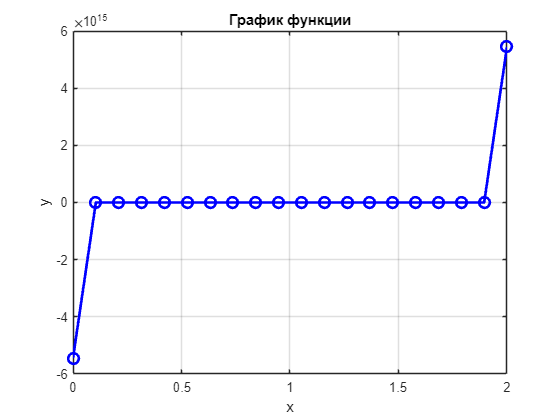

% Шаг 1: Построить 2х-мерный график функции при n=const и x=[0;2], число точек 20
y_values = a./sin(k_values(1).*phi_values);

figure;
plot(x_values, y_values, '-o', 'Color', 'blue', 'LineWidth', 2, 'MarkerSize', 8);
title('График функции');
xlabel('x');
ylabel('y');
grid on;
grid on;

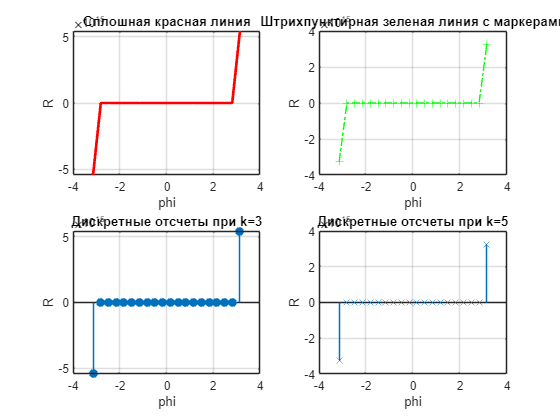

% Шаг 2: Построить два 2х-мерных графика при разных x = const
figure;
subplot(2, 2, 1);
plot(phi_values, a./sin(k_values(1)*phi_values), 'r-', 'LineWidth', 2);
title('Сплошная красная линия');
xlabel('phi');
ylabel('R');
grid on;

subplot(2, 2, 2);
plot(phi_values, a./sin(k_values(2)*phi_values), 'g+-.');
title('Штрихпунктирная зеленая линия с маркерами');
xlabel('phi');
ylabel('R');
grid on;

subplot(2, 2, 3);
stem(phi_values, a./sin(k_values(1)*phi_values), 'filled', 'Marker', 'o', 'MarkerSize', 6);
title('Дискретные отсчеты при k=3');
xlabel('phi');
ylabel('R');
grid on;

subplot(2, 2, 4);
stem(phi_values, a./sin(k_values(2)*phi_values), 'filled', 'Marker', 'x', 'MarkerSize', 6);
title('Дискретные отсчеты при k=5');
xlabel('phi');
ylabel('R');
grid on;

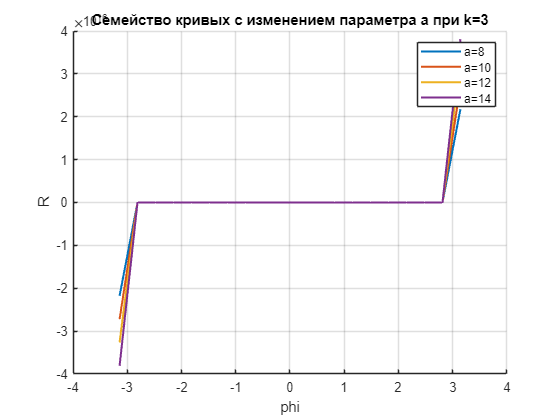

% Шаг 3: Построить семейство кривых, меняя значение параметра a от 8 до 14 с шагом 2
figure;
hold on;
for a_param = 8:2:14
    plot(phi_values, a_param./sin(k_values(1)*phi_values), 'LineWidth', 1.5);
end
hold off;
title('Семейство кривых с изменением параметра a при k=3');
xlabel('phi');
ylabel('R');
legend('a=8', 'a=10', 'a=12', 'a=14');
grid on;

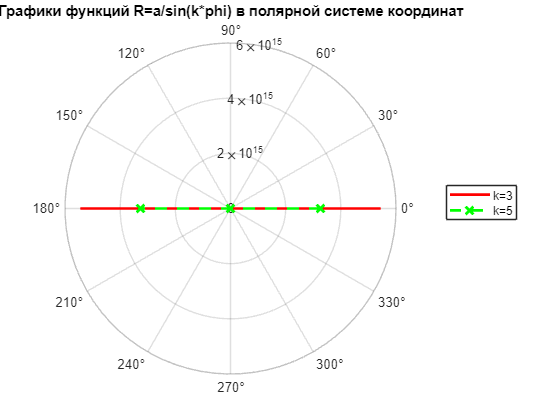

% Шаг 4: Построить в полярной системе координат графики функций для phi ∈ [-pi, pi] с шагом 0.1
figure;
polarplot(phi_values, a./sin(k_values(1)*phi_values), '-r', 'LineWidth', 2);
hold on;
polarplot(phi_values, a./sin(k_values(2)*phi_values), '--g', 'LineWidth', 2, 'Marker', 'x', 'MarkerSize', 8);
hold off;
title('Графики функций R=a/sin(k*phi) в полярной системе координат');
legend('k=3', 'k=5');
grid on;

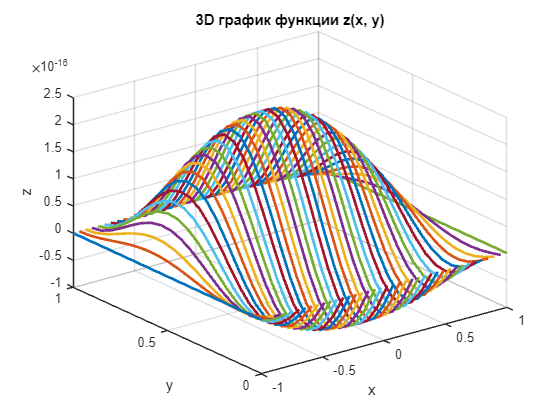

% Шаг 5: Построить 3D график функции z(x, y) = 4 * sin(2*pi) * cos(1.5*pi*y) * (1 - x^2) * y * (1 - y)
[x_values_3d, y_values_3d] = meshgrid(linspace(-1, 1, 40), linspace(0, 1, 20));
z_values_3d = 4 * sin(2*pi) .* cos(1.5*pi*y_values_3d) .* (1 - x_values_3d.^2) .* y_values_3d .* (1 - y_values_3d);

figure;
plot3(x_values_3d, y_values_3d, z_values_3d, 'LineWidth', 2);
title('3D график функции z(x, y)');
xlabel('x');
ylabel('y');
zlabel('z');
grid on;

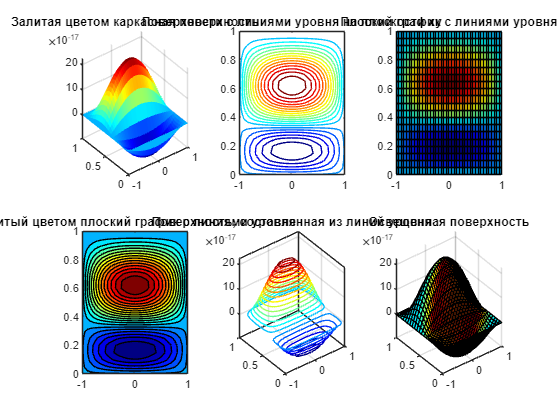

% Шаг 6: Варианты 3х-мерного графика с шагом 0.05
step = 0.05;
[x_values_3d_step, y_values_3d_step] = meshgrid(-1:step:1, 0:step:1);
z_values_3d_step = 4 * sin(2*pi) .* cos(1.5*pi*y_values_3d_step) .* (1 - x_values_3d_step.^2) .* y_values_3d_step .* (1 - y_values_3d_step);

figure;

subplot(2, 3, 1);
surf(x_values_3d_step, y_values_3d_step, z_values_3d_step, 'EdgeColor', 'none');
title('Залитая цветом каркасная поверхность');

subplot(2, 3, 2);
contour(x_values_3d_step, y_values_3d_step, z_values_3d_step, 20);
title('Поверхности с линиями уровня на плоскости xy');

subplot(2, 3, 3);
pcolor(x_values_3d_step, y_values_3d_step, z_values_3d_step);
title('Плоский график с линиями уровня');

subplot(2, 3, 4);
contourf(x_values_3d_step, y_values_3d_step, z_values_3d_step, 20);
title('Залитый цветом плоский график с линиями уровня');

subplot(2, 3, 5);
contour3(x_values_3d_step, y_values_3d_step, z_values_3d_step, 20);
title('Поверхность, составленная из линий уровня');

subplot(2, 3, 6);
surfl(x_values_3d_step, y_values_3d_step, z_values_3d_step);
title('Освещенная поверхность');

colormap('jet');